# Ressonância

clear all;
clc;
close all;


## Ressonância da função


$$G(s) = \frac{1}{s^2+s+1}$$


## Determinando os pólos


roots([1 1 1])

ans =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i


## Visualizando os polos

%%% Variável s = sigma + j omega

sigma = linspace(-1,1,100);
omega = linspace(-1,1,100);

G = @(sigma,omega) 1./((sigma+j*omega).^2+(sigma+j*omega) + 1)

G = function_handle with value:
    @(sigma,omega)1./((sigma+j*omega).^2+(sigma+j*omega)+1)



for m=1:100
    for n=1:100
      ganho(m,n) = G(sigma(m),omega(n));
    end
end

## Visualizando

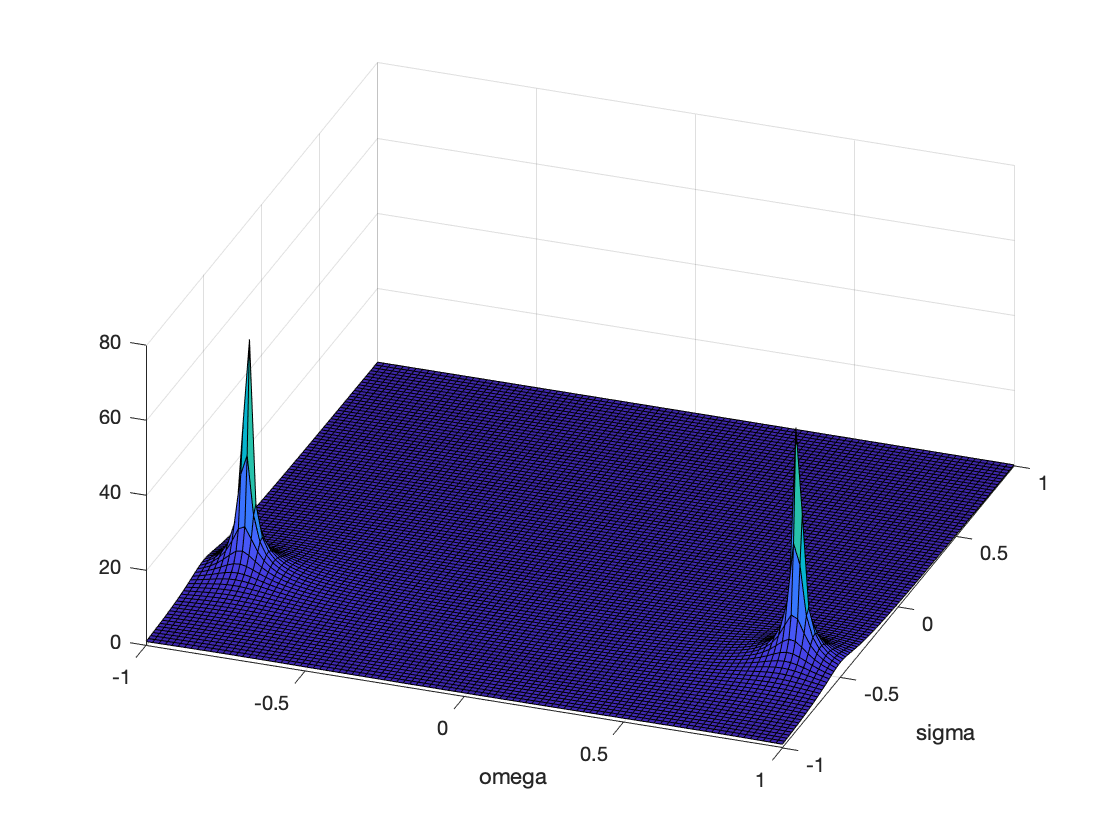


surf(sigma,omega,abs(ganho));
xlabel('omega')
ylabel('sigma'), view(20,45)


roots([1 1 1])

ans =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i
